MA-1006

Grupo: 01

Estudiante: Josef Ruzicka y Johan Avalos

Carnet: B87095 y C00817

# Tarea #4

**Instrucciones:**				

- Todo debe trabajarlo en este .mlx

- Si realiza procesos a mano puede agregar las imágenes insertándolas.

- Recuerde que puede consultar con el docente si tiene dudas. 

- Para las M-funciones procure comentar para indicar que es lo que se hace en cada paso. 

## Ejercicio

Lea del **Capitulo 9** del Mathews y Fink la seccion 9.9 con respecto al metodo de diferencias finitas. 

Modifique los programas 9.11 y 9.12 y utilicelos para aproximar la solucion del problema:


$$x''(t) = \frac{2t}{1+t^2} x'(t) - \frac{2}{1+t^2} x(t) + 1$$


en donde $x(0) = 1.25, \, x(4) =-0.95$, en el intervalo $[0,4]$, utilizando $h=0.05$. 

- Compare sus resultados con la tabla de la pagina 550. Luego calcule un vector de errores absolutos de las aproximaciones obtenidas con respecto a las imagenes exactas.

- Realice una grafica en la que se muestre la solucion exacta del problema junto con los nodos de la aproximacion que se realizo. 

% funciones de coeficientes de la ecuacion
p = @(t) (2.*t)./(1+t.^2);
q = @(t) -2./(1+t.^2);
r = @(t) 1+0.*t;
% intervalo
a = 0;
b = 4;
% alpha y beta
x0 = 1.25;
x4 = -0.95;
% tamano de intervalo
h = 0.05;
N = 80; % porque (4-0)/N = 0.05 => N = 80

format long
disp('Aqui las aproximaciones obtenidas con diferencias finitas')

Aqui las aproximaciones obtenidas con diferencias finitas


disp('Notese que deben observarse los indices multiples de 5 unicamente para comparar con la tabla del libro.')

Notese que deben observarse los indices multiples de 5 unicamente para comparar con la tabla del libro.


disp('Los valores fueron comparados con el libro satisfactoriamente')

Los valores fueron comparados con el libro satisfactoriamente


F = findiff(p, q, r, a, b, x0, x4, N)

F =                    0   1.250000000000000
   0.050000000000000   1.272387549621825
   0.100000000000000   1.291031349243650
   0.150000000000000   1.305950055581893
   0.200000000000000   1.317174456813893
   0.250000000000000   1.324747028667807
   0.300000000000000   1.328721342572205
   0.350000000000000   1.329161352015460
   0.400000000000000   1.326140586409336
   0.450000000000000   1.319741282595939


%F(:,2)


% Vector de errores
f_exac = @(t) 1.25 + 0.486089652.*t - 2.25.*t.^2 + 2.*t.*atan(t) + (1/2).*(t.^2 - 1).*log(1 + t.^2);
disp('Los valores fueron comparados con el libro satisfactoriamente')

Los valores fueron comparados con el libro satisfactoriamente


V_exac = f_exac(F(:,1))

V_exac =    1.250000000000000
   1.272430003173149
   1.291117281925914
   1.306080446965956
   1.317350212026377
   1.324968953086978
   1.328990120497042
   1.329477529817422
   1.326504560340217
   1.320153291124282



disp('Aqui los errores absolutos')

Aqui los errores absolutos


V_err  = abs(V_exac(:) - F(:,2))

V_err =                    0
   0.000042453551324
   0.000085932682264
   0.000130391384063
   0.000175755212484
   0.000221924419171
   0.000268777924837
   0.000316177801962
   0.000363973930881
   0.000412008528343


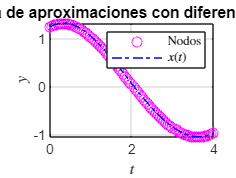


format default

% GRAFICACION
x=0:0.2:4;
x1=F(:,1);
y1=F(:,2);
y = V_exac;
plot(x1, y1, 'mo',  ...
     x1, y,  'b-.', ...
     'Linewidth',0.5)
%axis([1 4 -1 'inf'])
grid on
title('Grafica de aproximaciones con diferencias finitas')  % Fórmulas en LaTex
xlabel('$t$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')
lg=legend('Nodos','$x(t)$', ...
    'Location','northeast');
set(lg,'Interpreter','latex')

function X=trisys(A,D,C,B)
% Programa Sistemas tridiagonales
% Resoluci[on del sistema CX=B
% donde C es matriz tridiagonal

% Datos
% - A es la subdiagonal de la matriz de los coeficientes
% - D e la diagonal principal de la matriz de los coeficientes
% - C es la superdiagonal de la matriz de los coeficientes
% - B es el vector de los t[erminos independientes del sistema lineal
% Resultado
% - X es el vector soluci[on
    N = length(B);
    for k = 2 : N
        mult = A(k-1) / D(k-1);
        D(k) = D(k) - mult*C(k-1);
        B(k) = B(k) - mult*B(k-1);
    end
    X(N) = B(N) / D(N);
    for k= N-1:-1:1
        X(k) = (B(k) - C(k) * X(k+1)) / D(k);
    end
end

function F=findiff(p, q, r, a, b, alpha, beta, N)
% Datos
% - p,q y r son las funciones coeficientes de la ecuaci[on almacenadas como
%   cadenas de caracteres 'p', 'q', y 'r'
% - a y b son los exremos izquierdo y derecho del intervalo
% - alpha=x(a) y beta=x(b) son los valores en la frontera
% N es el n[umero de pasos
% Resultado
% - F=[T' X'] siendo T' el vector de orden 1 x N de los nodos y X' el
% vector 1 x N de los valores

% Inicializaci[on de los vectores y de h
T=zeros(1, N+1);
X=zeros(1, N-1);
Va=zeros(1, N-2);
Vb=zeros(1, N-1);
Vc=zeros(1, N-2);
Vd=zeros(1, N-1);
h=(b-a)/N;
% C[aculo del vector de los t[erminos independientes B en AX=B
Vt=a+h:h:a+h*(N-1);
%Vb=-h^2*feval(r,Vt);
Vb=-h^2*r(Vt);
%Vb(1)=Vb(1)+(1+h/2*feval(p,Vt(1)))*alpha;
%Vb(N-1)=Vb(N-1)+(1-h/2*feval(p,Vt(N-1)))*beta;
% A mi no me da error el feval, pero por si a caso para la revision
Vb(1)=Vb(1)+(1+h/2*p(Vt(1)))*alpha;
Vb(N-1)=Vb(N-1)+(1-h/2*p(Vt(N-1)))*beta;
% C[alculo de la diagonal principal de A en AX=B
%Vd=2+h^2*feval(q, Vt);
Vd=2+h^2*q(Vt);
% C[alculo de la superdiagonal de A en AX=B
Vta=Vt(1,2:N-1);
%Va=-1-h/2*feval(p,Vta);
Va=-1-h/2*p(Vta);
% C[alculo de la subdiagonal de A en AX=B
Vtc=Vt(1,1:N-2);
%Vc=-1+h/2*feval(p,Vtc);
Vc=-1+h/2*p(Vtc);
% Resoluci[on de AX=B usando trisys
X=trisys(Va, Vd, Vc, Vb);
T=[a, Vt, b];
X=[alpha, X, beta];
F=[T' X'];
end